# Seismic Reservoir Prediction in Autoencoder

## Introduction

An [autoencoder](https://en.wikipedia.org/wiki/Autoencoder) is a type of [artificial neural network](https://en.wikipedia.org/wiki/Artificial_neural_network) used to learn [efficient data codings](https://en.wikipedia.org/wiki/Feature_learning) in an [unsupervised](https://en.wikipedia.org/wiki/Unsupervised_learning) manner.[[1]](https://en.wikipedia.org/wiki/Autoencoder#cite_note-1)[[2]](https://en.wikipedia.org/wiki/Autoencoder#cite_note-2) The aim of an autoencoder is to learn a representation (encoding) for a set of data, typically for the purpose of [dimensionality reduction](https://en.wikipedia.org/wiki/Dimensionality_reduction). Recently, the autoencoder concept has become more widely used for learning [generative models](https://en.wikipedia.org/wiki/Generative_model) of data.(Via Wiki)

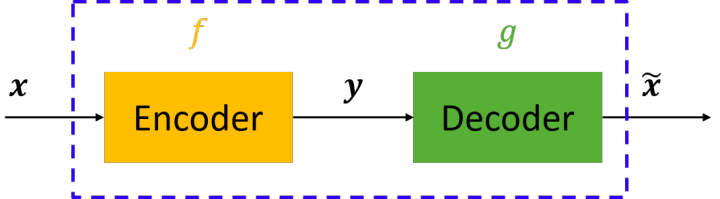

Linking:[https://www.zhihu.com/question/41490383](https://www.zhihu.com/question/41490383)

## Load data

path = '/Users/maihao/Documents/MATLAB/DeepLearnBookPractice';
filename = 'ANN_GA_FWD_database.xlsx';
sheet = 2;
xlRange='D:T';  
pwd

ans = '/Users/maihao/Documents/MATLAB/DeepLearnBookPractice'

subsetA=xlsread(filename,sheet,xlRange);%这样导入没有标题名字
ylRange = 'U:AF';
subsetB=xlsread(filename,sheet,ylRange);%这样导入没有标题名字

## Merge Input Output

subsetA = subsetA(2:end,:);
datasets = [subsetA subsetB];

##  Transpose for training 

datasets = datasets';

## Normlization 0-1

[datasets,info] = mapminmax(datasets,0,1);

## Spilt Training data(85%) and Test data (15%) 

[D, ndata] = size(datasets)      %ndata样本数，D维数

D = 29

ndata = 13815

R = randperm(ndata);         %1到n这些数随机打乱得到的一个随机数字序列作为索引
num_test = floor(ndata*0.15)

num_test = 2072

Xtest = datasets(:,R(1:num_test));  %以索引的前15%个数据点作为测试样本Xtest
%R(1:num_test) = [];
Xtraining = datasets(:,R(num_test+1:end));          %剩下的数据作为训练样本Xtraining
num_training = size(Xtraining,2)%num_training；训练样本数

num_training = 11743

## AutoEncoder

% hiddenSize = 50;
% autoenc = trainAutoencoder(Xtraining,hiddenSize,...
%         'L2WeightRegularization',0.004,...
%         'SparsityRegularization',4,...
%         'SparsityProportion',0.15); %saved as AEResult.mat 
% laod AEResult.mat  then use  is better 
% XReconstructed = predict(autoenc,Xtraining');
autoenc = trainAutoencoder(Xtraining);
XReconstructed = predict(autoenc,Xtraining);
mseError = mse(Xtraining-XReconstructed)  %   above green code performance better  

mseError = 0.0370

 XTestResult = predict(autoenc,Xtest);
 mseError = mse(Xtest-XTestResult)

mseError = 0.0371

## Normlization Data Return

 TrainDataResult = mapminmax('reverse',XReconstructed,info);
 datasets = mapminmax('reverse',datasets,info);
 XtrainingReturn = datasets(:,R(num_test+1:end)); 
 